% Defining obstacles in the workspace
% For each obstacle, we also define the the zone of influence around it.

% Initializing array for storing the information for the obstacles 
% and the zone of influence around the obstacle
%--------------------------------------------------------------------------
% P:     stores the zone of influences for all the obstacles
% pgon:  stores the information for all the obstacles in the workspace
% P_r:   stores the parameters of the various zone of influence
%--------------------------------------------------------------------------
P = repmat(polyshape,1,4);
pgon = repmat(polyshape,1,4);
P_r = zeros(3,4);

% Defining the paramaters for various obstacles
% pgon(1): Square obstacle
pgon(1) = polyshape([3 3 4 4],[3 4 4 3]);
P_r(1,1) = 2;
P_r(1,2) = 3.5;
P_r(1,3) = 3.5;

% pgon(2): Triangular obstacle
pgon(2) = polyshape([3 4 4],[6 6 7]);
P_r(2,1) = 1;
P_r(2,2) = 20/3;
P_r(2,3) = 19/3;

% pgon(3): Circular obstacle
xc = 6;
yc = 6;
r = 1;
n = 100;
theta = (0:n-1)*(2*pi/n);
x = xc + r*cos(theta);
y = yc + r*sin(theta);
pgon(3)= polyshape(x,y);
P_r(3,1) = 2;
P_r(3,2) = 6;
P_r(3,3) = 6;

% pgon(4): Square obstacle
pgon(4) = polyshape([5 5 6 6],[3 4 4 3]);
P_r(4,1) = 2;
P_r(4,2) = 5.5;
P_r(4,3) = 3.5;

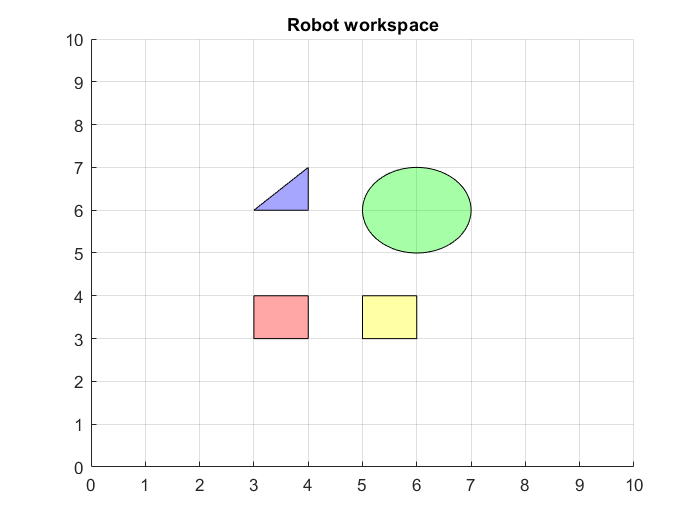

% Plotting the robot workspace
f1 = figure;
figure(f1)
axis([0 10 0 10])
title("Robot workspace")
hold on
grid on
plot(pgon(1),'Facecolor', 'r')
plot(pgon(2), 'Facecolor', 'b')
plot(pgon(3), 'Facecolor', 'g')
plot(pgon(4), 'Facecolor', 'y')

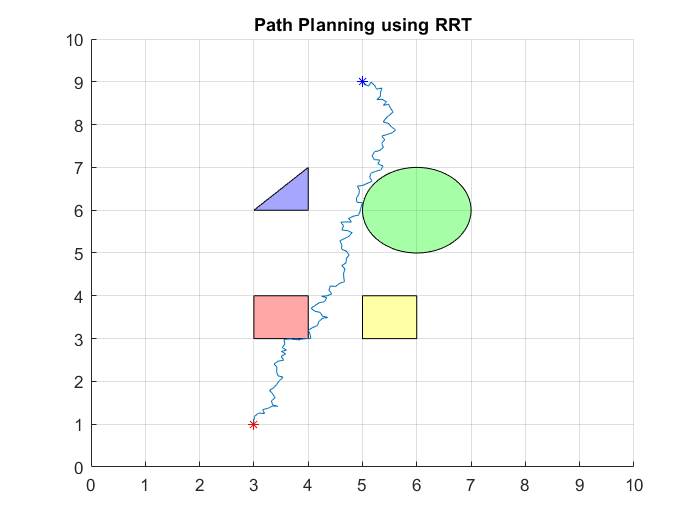

% Defining the start and goal points
start = [3,1];
goal = [5,9];

title("Path Planning using RRT")
plot(start(1),start(2),'r*')
plot(goal(1), goal(2),'b*')
current = start;

robot_step = 0.1;

while(calcDistance(current,goal)>0.1)
    temp = current;
    while true
        a = -pi/2;
        b = pi/2;
        n = 1;
        theta = a + (b-a).*rand(n,1);
        T = [cos(theta) sin(theta);-sin(theta) cos(theta)];
        v = [goal(1) - current(1);goal(2) - current(2)];
        z = T*v;
        z = (z/(sqrt(z(1)^2 + z(2)^2)))*robot_step;
        current(1) = current(1) + z(1);
        current(2) = current(2) + z(2);
        inside = 0;
        for i=1:4
            in = isinterior(pgon(i),current(1),current(2));
            if in==1
                inside = 1;
                break;
            end
        end
        
        if inside==1
            current = temp;
            continue;
        else
            break;
        end
    end
    line([temp(1), current(1)], [temp(2), current(2)]);
    pause(0.001);
end

function distance = calcDistance(a,b)
    distance = sqrt((a(1)-b(1))^2 + (a(2)-b(2))^2);
end